clear;

% lin prog
f = -[5 3];
A = [1 1; 5 2]; b = [4 10];
Aeq = []; beq = [];
lb = [0; 0];
ub = [inf; inf];

[x, fval] = linprog(f, A, b, Aeq, beq, lb, ub);

Optimal solution found.



disp("x(1) = " + x(1));

x(1) = 0.66667


disp("x(2) = " + x(2));

x(2) = 3.3333


disp("f(x) = " + fval);

f(x) = -13.3333


% matrix inequality 1
setlmis([]);
[X1, n, sX1] = lmivar(2, [2 3]);
[X2, n, sX2] = lmivar(2, [3 2]);
[X, n, sX] = lmivar(3, [sX1 zeros(2); zeros(3) sX2]);

A = rand(5); B = ones(5);

LMI_1 = newlmi;
lmiterm([LMI_1 1 1 X], A, A');

lmiterm([LMI_1 1 1 0], -B);

lmisys = getlmis;
[tmin, xfeas] = feasp(lmisys) %error value and solution


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
* switching to QR
     1                        0.032266
     2                        0.010022
     3                        0.010022
     4                       -0.013313

 Result:  best value of t:    -0.013313
          f-radius saturation:  0.000% of R =  1.00e+09
 


tmin = -0.0133

xfeas =    -4.6646
  968.8109
    3.4210
 -960.1382
   -5.5671
   -0.4475
    0.4141
    0.8780
   -3.3815
  694.4534


X_ans = dec2mat(lmisys, xfeas, X)

X_ans =    -4.6646  968.8109    3.4210         0         0
 -960.1382   -5.5671   -0.4475         0         0
         0         0         0    0.4141    0.8780
         0         0         0   -3.3815  694.4534
         0         0         0 -689.9559   -6.1195


% lin prg with matrix inequality
setlmis([]);
P = lmivar(1, [3 1]);
gamma = lmivar(1, [1 0]);

A = [0 1 0; 0 0 1; -0.5 -1.2 -11.3]; B = [0; 0; 1]; C = [1 1 0];

LMI_1 = newlmi;
lmiterm([LMI_1 1 1 P], 1, A', "s");
lmiterm([LMI_1 1 1 0], C' * C);
lmiterm([LMI_1 1 2 P], 1, B);
lmiterm([LMI_1 2 1 P], B', 1);
lmiterm([LMI_1 2 2 gamma], -1, 1);

LMI_2 = newlmi;
lmiterm([-LMI_2 1 1 P], 1, 1);
lmisys = getlmis;
Dcnbr = decnbr(lmisys); %7
c = zeros(Dcnbr, 1);
for j = 1:Dcnbr
    c(j) = defcx(lmisys, j, gamma);
end
% or just [0;0;0;0;0;0;1];
[copt, xopt] = mincx(lmisys, c)


 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4                  35.920198
     5                  34.282756
     6                  34.282756
     7                  27.802488
     8                  27.316369
     9                  27.316369
***                 new lower bound:    17.635105
    10                  27.316369
***                 new lower bound:    22.414663
    11                  26.380263
***                 new lower bound:    25.402241
    12                  26.184506
***                 new lower bound:    25.696529
    13                  26.151380
***                 new lower bound:    25.902941

 Result:  feasible solution of required accuracy
          best objective value:    26.151380
          guaranteed relative accuracy:  9.50e-03
          f-radius saturation:  0.000% of R =  1.00e+09 
 


copt = 26.1514

xopt =   351.1053
  -16.8836
   12.4561
    5.0819
   -8.4335
   97.1251
   26.1514


dec2mat(lmisys, xopt, P)

ans =   351.1053  -16.8836    5.0819
  -16.8836   12.4561   -8.4335
    5.0819   -8.4335   97.1251


dec2mat(lmisys, xopt, gamma)

ans = 26.1514

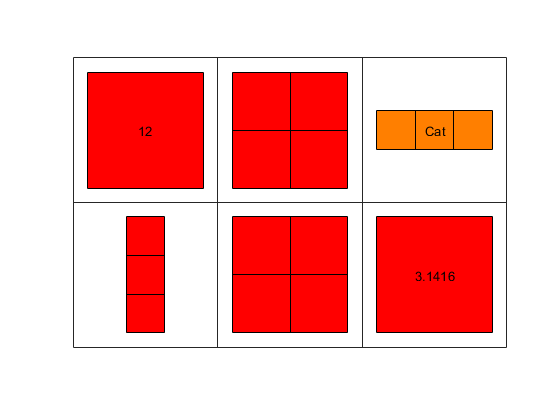

%cell operations
tmp_cell = {products(1) products(2) products(3, 1); products(3, 1) products(2) products(1)};
%trying different ways
tmp_cell(1, 1) = {12};
tmp_cell(2, 3) = {pi};

tmp_cell{1, 2} = magic(2);
tmp_cell{2, 2} = eye(2);

tmp_cell{1, 3} = 'Cat';
tmp_cell{2, 1} = [0.1:0.2:0.5]';

cellplot(tmp_cell)


tmp_cell_plus_1 = tmp_cell;

for k = 1: numel(tmp_cell)
    if isnumeric(tmp_cell{k})
        tmp_cell_plus_1{k} = tmp_cell{k} + 1;
    end
end
%test
tmp_cell_plus_1{2, 1}

ans =     1.1000
    1.3000
    1.5000


products =  cell(3, 4);
%not the best way but it is clearer for me
products{1, 1} = "apple"; products{1, 2} = 123; products{1, 3} = 1200; products{1, 4} = 1.2; 
products{2, 1} = "banana"; products{2, 2} = 211; products{1, 3} = 1800; products{2, 4} = 1.4; 
products{3, 1} = "vodka"; products{3, 2} = 456; products{1, 3} = 0; products{3, 4} = 0.5; 

fields = {'name', 'price', 'kkal', 'kg'};
struct_products = cell2struct(products, fields, 2);

x = 200;
disp("products more expensive than " + x);

products more expensive than 200


for j=1:length(struct_products)
    if struct_products(j).price > x
        disp(struct_products(j).name)
    end
end

banana
vodka


text = 'Simulink is a simulation and model-based design environment for dynamic and embedded systems, integrated with MATLAB. Simulink, also developed by MathWorks, is a data flow graphical programming language tool for modelling, simulating and analyzing multi-domain dynamic systems. It is basically a graphical block diagramming tool with customizable set of block libraries.'

text = 'Simulink is a simulation and model-based design environment for dynamic and embedded systems, integrated with MATLAB. Simulink, also developed by MathWorks, is a data flow graphical programming language tool for modelling, simulating and analyzing multi-domain dynamic systems. It is basically a graphical block diagramming tool with customizable set of block libraries.'

text = text(regexp(text, '[^.,]'))

text = 'Simulink is a simulation and model-based design environment for dynamic and embedded systems integrated with MATLAB Simulink also developed by MathWorks is a data flow graphical programming language tool for modelling simulating and analyzing multi-domain dynamic systems It is basically a graphical block diagramming tool with customizable set of block libraries'

text_split = strsplit(text);

all_words_sorted = sort(unique(text_split));
cap_words = all_words_sorted(1:4)

cap_words = 1×4 cell array
    {'It'}    {'MATLAB'}    {'MathWorks'}    {'Simulink'}


other_words = all_words_sorted(5:end)

other_words = 1×33 cell array
    {'a'}    {'also'}    {'analyzing'}    {'and'}    {'basically'}    {'block'}    {'by'}    {'customizable'}    {'data'}    {'design'}    {'developed'}    {'diagramming'}    {'dynamic'}    {'embedded'}    {'environment'}    {'flow'}    {'for'}    {'graphical'}    {'integrated'}    {'is'}    {'language'}    {'libraries'}    {'model-based'}    {'modelling'}    {'multi-domain'}    {'of'}    {'programming'}    {'set'}    {'simulating'}    {'simulation'}    {'systems'}    {'tool'}    {'with'}



TF = isstrprop(text, "upper");
text(TF) = lower(text(TF));
text_split = strsplit(text);
all_words_sorted = sort(unique(text_split))

all_words_sorted = 1×37 cell array
    {'a'}    {'also'}    {'analyzing'}    {'and'}    {'basically'}    {'block'}    {'by'}    {'customizable'}    {'data'}    {'design'}    {'developed'}    {'diagramming'}    {'dynamic'}    {'embedded'}    {'environment'}    {'flow'}    {'for'}    {'graphical'}    {'integrated'}    {'is'}    {'it'}    {'language'}    {'libraries'}    {'mathworks'}    {'matlab'}    {'model-based'}    {'modelling'}    {'multi-domain'}    {'of'}    {'programming'}    {'set'}    {'simulating'}    {'simulation'}    {'simulink'}    {'systems'}    {'tool'}    {'with'}
